% f''(x) = [f(x+h) - 2*f(x) + f(x-h)]/ h²
h = 0.1;
x = 0:h:0.7;
f =@(x) 1 + x + x.^4;
%faux = sym(f)
%df = matlabFunction(diff(faux))
%dxSym = df(x)

[h,dx,e]=calcularError(f,3)

h =     1.0000    0.5000    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000


dx =    50.0000   75.5000   85.5556   90.8750   94.1600   96.3889   98.0000   99.2188  100.1728  100.9400


e =     0.5413    0.3073    0.2151    0.1663    0.1361    0.1157    0.1009    0.0897    0.0810    0.0739


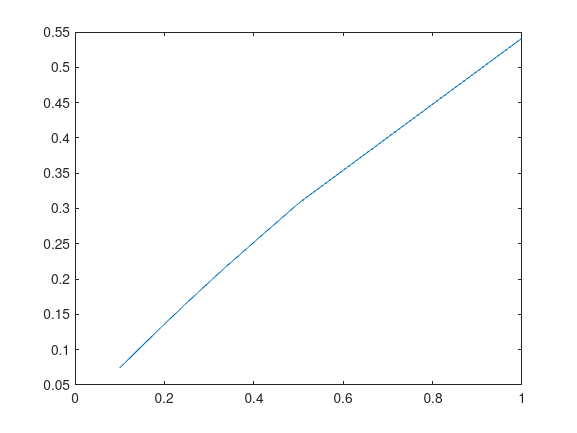

plot(h,e)

function [hVec, dxVec, eVec]  = calcularError(f, x)
    H = 1; %Valor original de h
    N = 10; %Cuantas vueltas vamos a dar
    df = matlabFunction(diff(sym(f))); %Convierto en funcion anonima a la derivada
    hVec = []; %Vector de las h
    dxVec = []; %Vector de las estimaciones
    eVec = []; %Vector de los errores
    for i=1:1:N%La longitud de v
        h = H/i; % El valor del cambio durante la iteracion
        est=(f(x) - 2*f(x-h) + f(x-2*h)) / h^2;%Estimo la derivada
        dfR=df(x);%Calculo la derivada real
        error = abs(((dfR - est)./dfR));%Calculo el error
        %Hago append de los vectores
        hVec = [hVec,h];
        dxVec = [dxVec,est];
        eVec = [eVec,error];
    end
end